# Worksheet 4: Thermodynamics

#### Due Friday, October 30

As in our previous worksheets, there are three main parts (plus some reading questions at the beginning and reflection questions at the end), which we are expecting that you will be able to start in studio during our three class sessions this week, and comfortably finish as homework. You are welcome to work ahead, but you should plan to use the class time to collaborate with the other students at your studio table.

### Learning Objectives

After completing this worksheet, you should be able to:

- Distinguish intensive and extensive properties of a system. 

- Describe heat transfer mechanisms (convection, conduction, and radiation) and identify the most important heat transfer mechanisms in a thermodynamic system. 

- Draw a stock and flow diagram for a thermodynamic system and write the corresponding ODEs. 

- Calculate energy flows when there are multiple heat transfer mechanisms at play. 

- Simulate a simple thermodynamic system. 

## 1. Reading Questions

Please read the Introduction to Thermal Systems handout, then answer the following questions. 

1.1. What is an intensive state variable? What is an extensive state variable? Give an example of each. 

**Response:**

An intensive state variable is not related to the amount of something you have (ex. color, temperature), whereas an extensive state variable is dependent on the amount of something you have.

1.2. What's the relationship between energy, temperature, and specific heat? Report it in math and in words. 

**Response:**


$$Q=\textrm{mc}\Delta T\;\textrm{therefore}\frac{Q\;}{\textrm{mc}}=\Delta T$$


Temperature is energy divided by mass and specific heat.

Specific heat is the amount of energy a substance absorbs per Kelvin that it gets hotter.

1.3. Describe conduction and convection and clarify the difference between them. 

**Response:**

Conduction is the transfer of thermal energy between two solid objects that are touching, via the atoms/molecules of one bumping against the molecules of the other.

Convection is the transfer of thermal energy between a fluid and a fluid or a solid. 

1.4. In what situations is radiation an important heat transfer mechanism? 

**Response:**

At higher temperatures, more thermal energy is released by radiation, making it more important. Also, when in an environment where a significant amount of energy is being delivered by radiation (ex. under a heat lamp, in the sun). Finally, in circumstances where conduction or convection don't occur (ex. in space), radiation can be the only (?) means of heat transfer, therefore making it far more important.

For coffee specifically, most thermoses work by suspending the coffee in an inner vessel that is sorrounded by a vaccum, preventing convection from occuring and minimizing conduction. In this circumstance (depending on the effectiveness of the thermos), radiation might become a significant factor.

## 2. The Model

In the reading, we saw one way of abstracting the system of a pot of water heating up. This week, we'll be focusing on the system of a cup of coffee that's cooling off. 

How might you abstract this system? Start with the simplest level of abstraction: identify the single most important heat transfer mechanism in this system and include only those flows.

2.1 Which heat transfer mechanism do you think is the most important in this system? Why is it the most important? 

**Response: **

We think that the convection with the air will be the most important because the mug is generally a decent insulator, as evidenced by the fact that the exterior of the mug is generally far cooler than the coffee inside.

2.2 Now, for the sake of all working on the same initial model, focus your attention on just the conduction flow through the walls of the coffee cup and neglect all other flows. Draw a schematic figure of the system (a simplified, informative picture) and label the important components. 

**Response: **

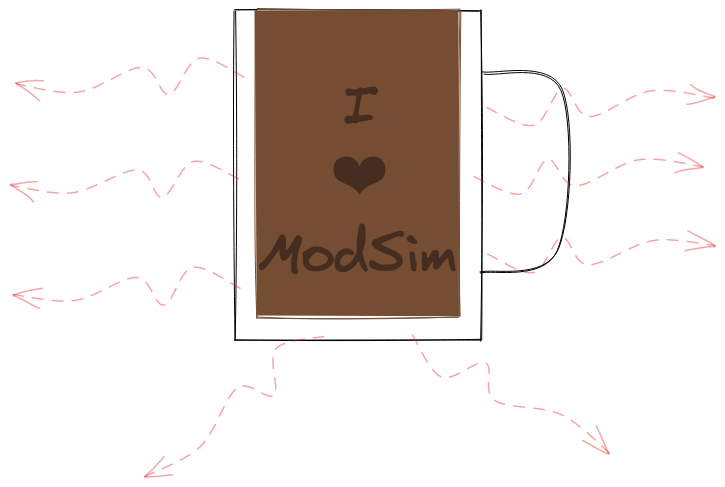

2.3 Draw a fully labeled stock and flow diagram of the system. 

**Response: **

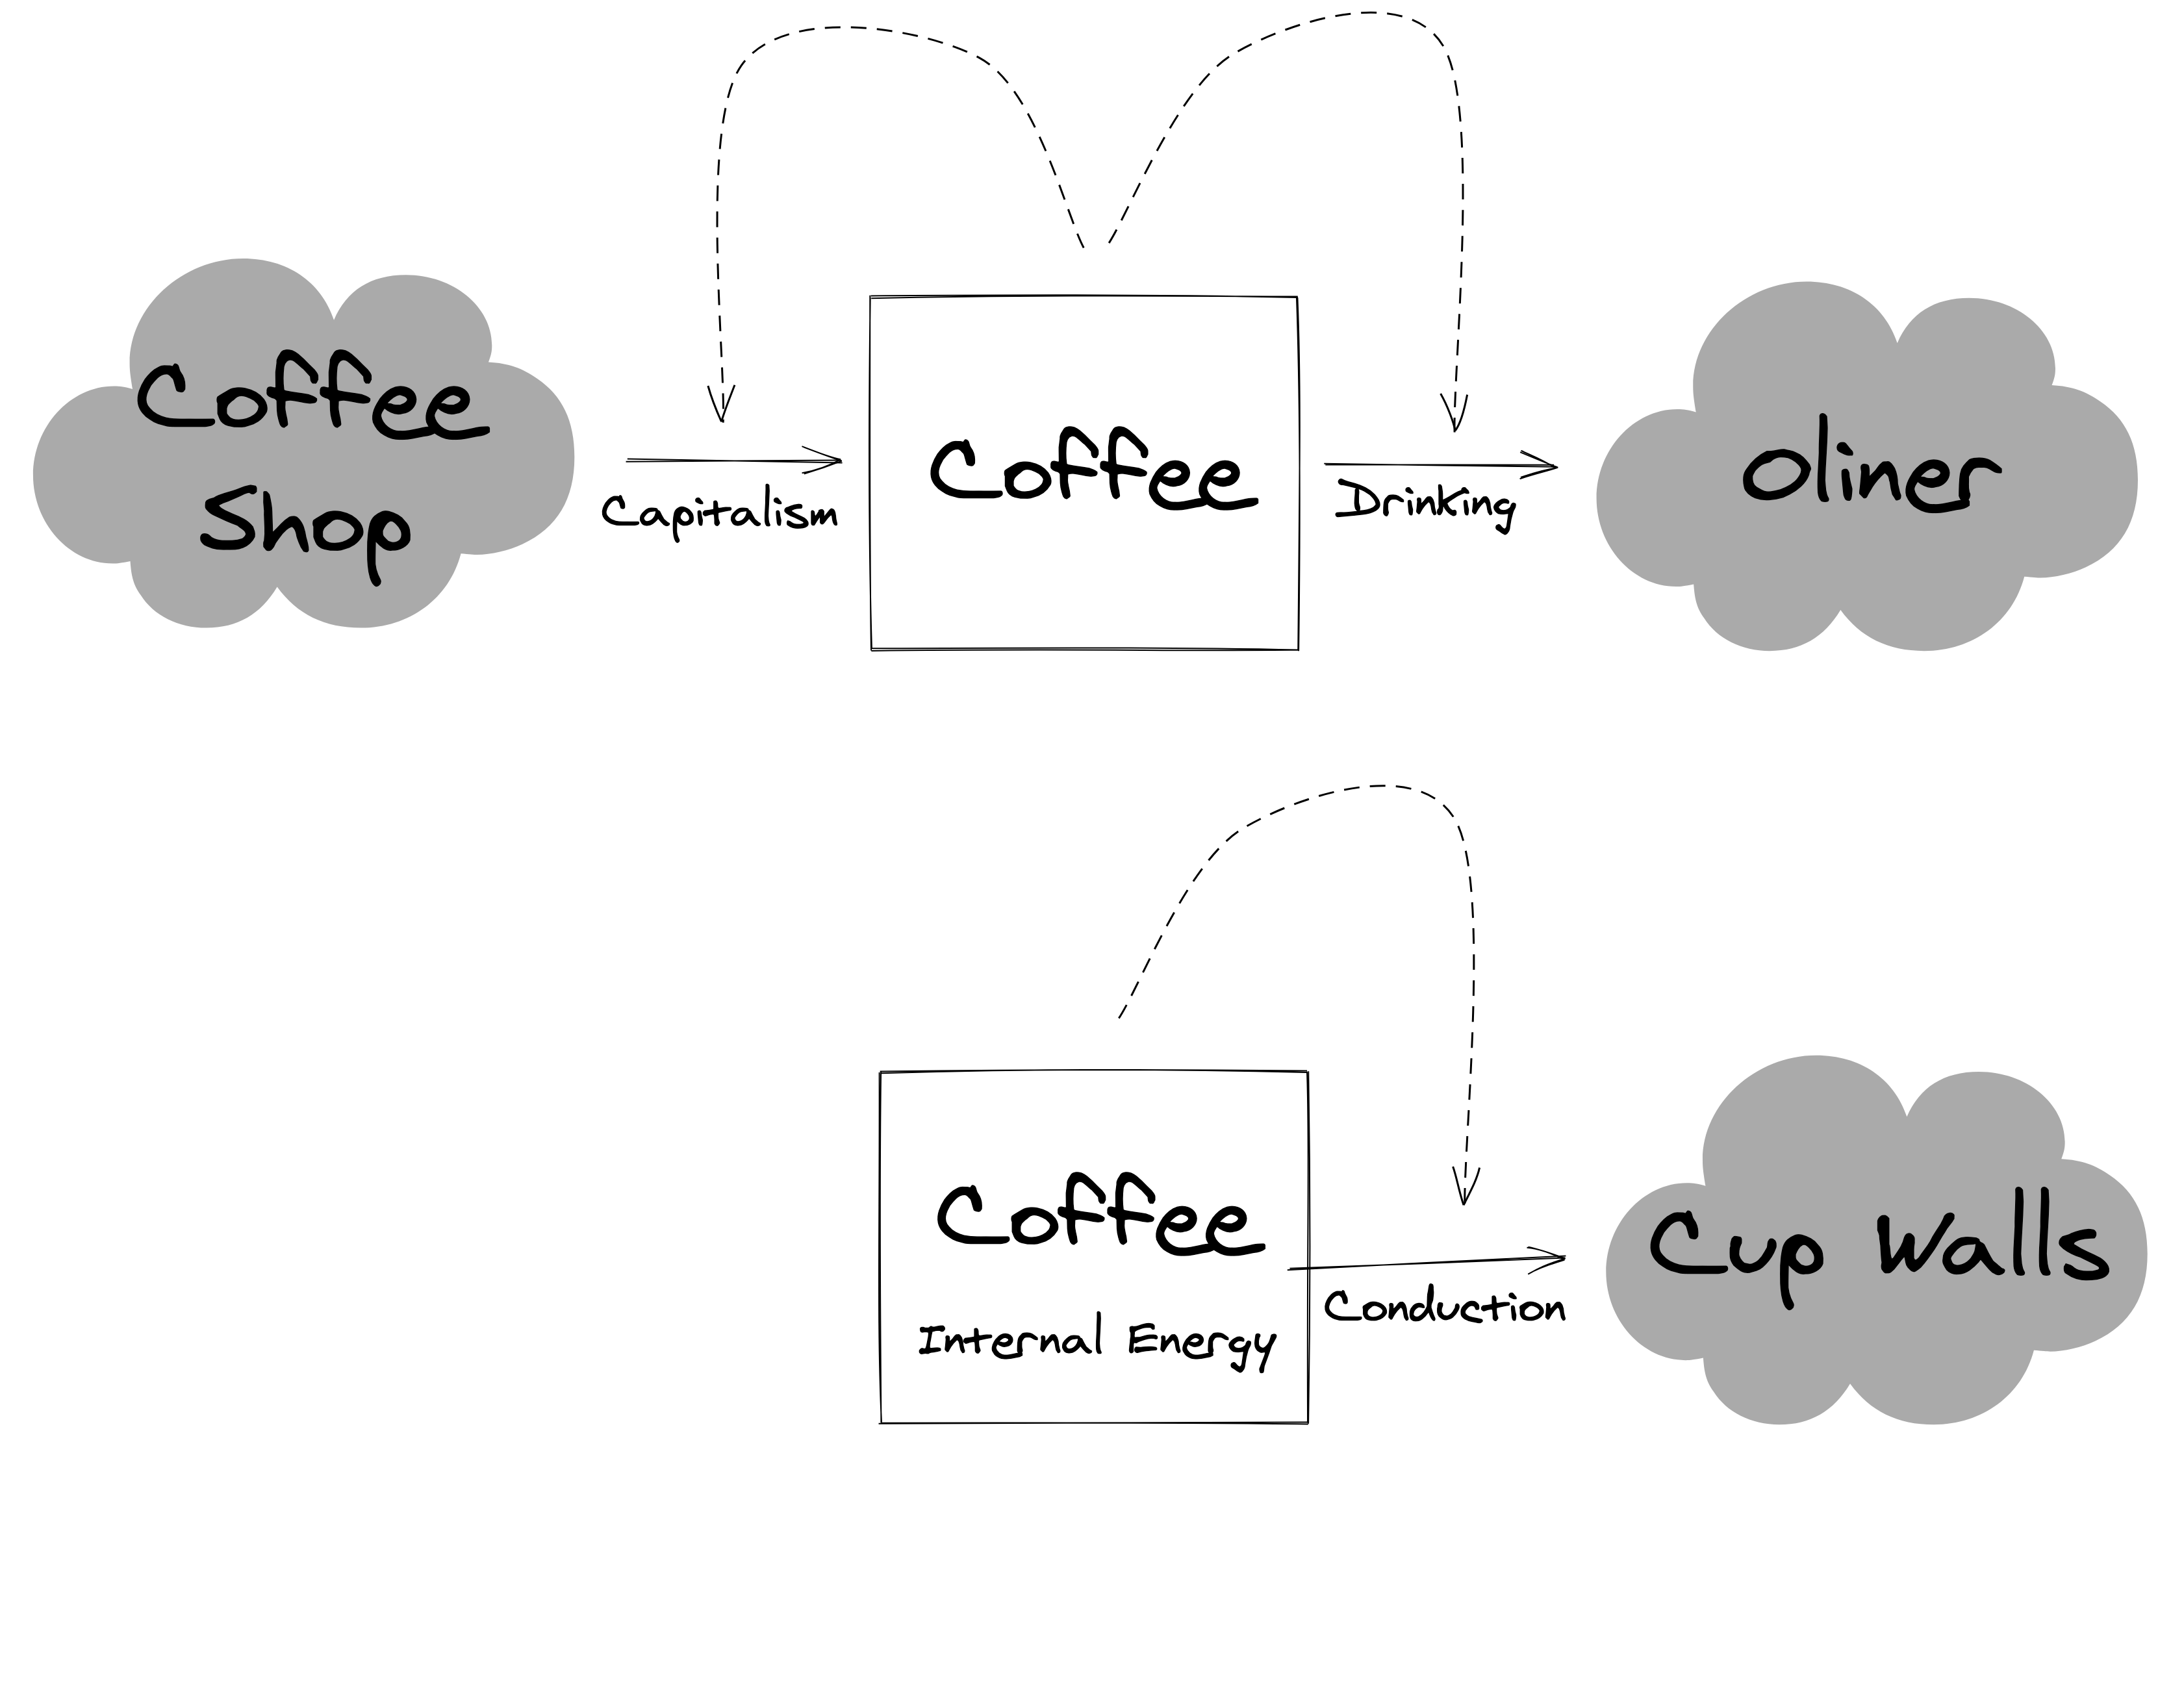

2.4 Based on your simplified stock and flow diagram, write the ODEs that describe this system. 

**Response:**


$$\frac{\mathrm{dU}}{\mathrm{dt}}=-\mathrm{aU}$$


2.5 Now think about what the next iteration of your model might be — an iteration that includes an additional flow and/or heat transfer mechanism. Describe in words your modified model and draw a schematic diagram of it.  

**Response: **

The next step would be to add convection with the air above the cup.

***PROGRESS CHECK: We are expecting you to complete the questions above before class on Wednesday. If you get stuck, we suggest consulting a CA or someone at your studio table before you come to class; this will help everyone benefit from collaborating during the studio time.***

## 3. Simulation of the Simplest Abstraction

You are now ready to implement the model in MATLAB at the simplest level of abstraction. Build a simulation of the system you described in diagrams and math in 2.2, 2.3, and 2.4, above (conduction through the coffee cup walls only). With your ODEs from above and the values below, you should have all the information you need to build and run this simulation. 

The modeling question we're aiming at is: If you want to drink your coffee when you get in the car for your drive, and you drink it at 76 C, how far in advance of leaving should you make your coffee? 

We recommend writing a function called coffee_cool() that returns the temperature of the coffee over time. Use the following values for your parameters and initial conditions and run the simulation for 30 minutes: 

- Initial temperature of coffee = 370 K 

- Initial temperature of the environment = 290 K

- Diameter of coffee cup = 8 cm 

- Height of coffee in cup = 10 cm 

- Thickness of coffee cup walls  = 0.7 cm 

- Thermal conductivity of cup walls = 1.5 W/(m*K)

- Specific heat of coffee = 4186 J/(kg*K) (same as water)

- Density of coffee = 1000 kg/m^3 (same as water)

*(Source for thermal conductivity: *[http://www.engineeringtoolbox.com/thermal-conductivity-d_429.html;](http://www.engineeringtoolbox.com/thermal-conductivity-d_429.html;)* see "porcelain".)*

3.1 Call your function here and plot the results (or include plotting the results in the function). 

**Response:**

% Your code here

3.2 Our function produces a graph that looks like this. Is it similar to yours? If not, why do you think it's different? 

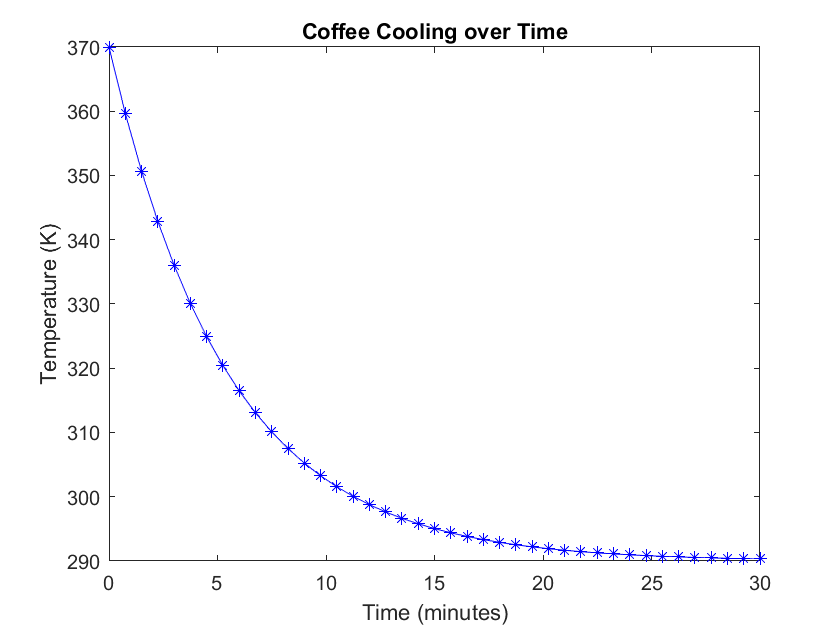

**Response: **

% Your response here 

3.3 Our modeling question, again, is: If you want to drink your coffee when you get in the car for your drive, and you drink it at 76 C, how far in advance of leaving should you make your coffee? Use the results you already generated to provide an approximate answer. 

**Response: **

% Your response here 

***PROGRESS CHECK: We are expecting you to complete the questions above before class on Friday. If you get stuck, we suggest consulting a CA or someone at your studio table before you come to class; this will help everyone benefit from collaborating during the studio time.***

## 4. Iteration! 

4.1 Once you've successfully modeled the cup of coffee cooling with just one heat transfer mechanism, you're ready to iterate. Look back at question 2.5: you drew a schematic diagram, but you didn't draw a stock and flow diagram or write ODEs. Now that we've talked in class about combining multiple heat transfer mechanisms (remember the "in series" and "in parallel" analogies), draw a stock and flow diagram for the system you sketched in question 2.5. 

*Note that if you included evaporation as the next flow you would include, we recommend setting that aside for now and choosing a different flow or heat transfer mechanism to add in. See the bottom of this worksheet for a bonus challenge on including evaporation. 

**Response: **

% Your diagram here 

4.2 Now copy your coffee cooling code to a new m-file and modify it for this abstraction of the system. Call it here and plot the results. 

**Response:**

% Your code here

4.3 Our code produces a figure that looks like this. Is it similar to yours? If not, why do you think it's different?

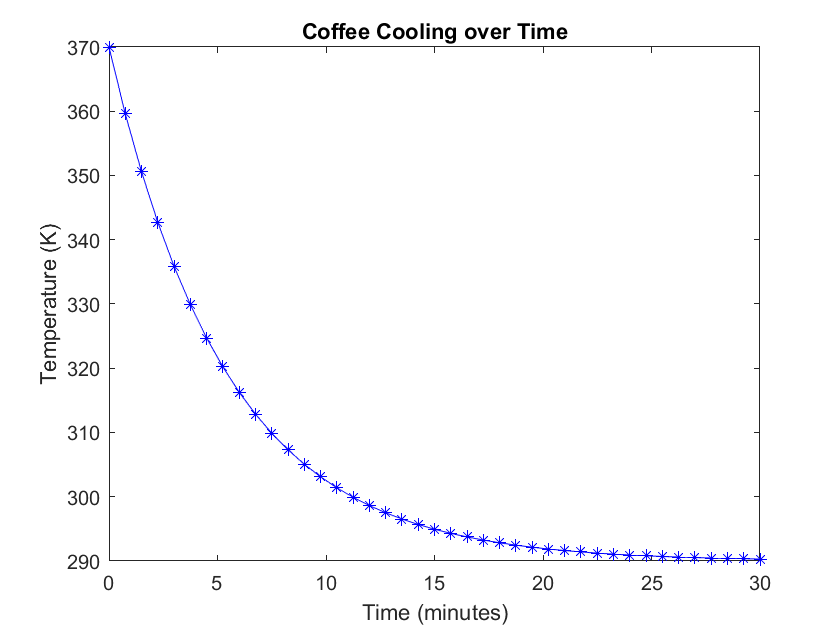

**Response: **

% Your response here 

4.4 Compare the figure produced by the first model and the figure produced by the second model: note the similarities and differences. What does this comparison tell you about the heat flows you've included in the two iterations of your model? 

**Response: **

% Your response here 

4.5 If you were to iterate on this model again, what would you add in? Do you think this next iteration is likely to  improve your results? Why or why not? 

**Response: **

% Your response here

***BONUS CHALLENGE: ****If you would like to take on an extra challenge, scroll to the bottom of the worksheet. That section is ****optional****. If you do tackle it, ****be sure you also complete all the other sections (1-5) of the worksheet before submitting.*** 

## 5. Reflection Questions

The purpose of this final section is to give you an opportunity to reflect on your experience in completing the worksheet. This information may be helpful for your studio instructor, but it is mainly intended to be helpful to you.

5.1. How did you decide which flows to include in your model in 2.1 and 2.5? Did you have some intuition for which would be most important? If so, where do you think that intuition came from? If not, did you discover anything from building this model that helped build some intuition about which flows might be most important? 

**Response:**

% Your text here

5.2. Think back on the parts of the worksheet that were trickiest for you: where you perhaps got stuck, needed help, or just needed to think longer and harder about your work. Were those spots mostly about the physics of heat transfer, designing your code (deciding how to write it and structure it), writing and debugging your code (making it actually work), or some other aspect of the modeling process? What can you do to keep smoothing out those rough spots? 

**Response:**

% Your text here

## Optional Bonus Challenge

We have not included evaporation in this model yet because it involves mass transfer as well as a phase change. If you'd like to take on the extra challenge, try iterating on your model to include evaporation. Start with a schematic diagram, a stock and flow diagram, and your ODEs before starting to modify your code. (And work in a new copy of the code so you preserve your exisiting work separately.) Even if you start on this and don't finish it, we'd like to see your work here if you attempt this. 

**Response: **

% Your figures and ODEs here

% Your code here